# 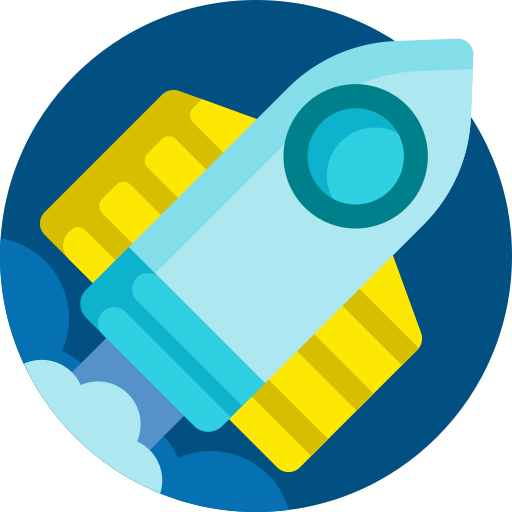

# **MEC3079S: Control Systems**

# Chapter 7 — Frequency response techniques

## 7.1 Introduction

As we have already learnt, the output response is made up of the natural response, $y_n(t)$, and forced response, $y_f(t)$, namely.

$y(t)=y_n(t)+y_f(t)$,

where the profile of the forced response matches that of the input signal, $u(t)$. We have also shown that in steady-state, the output response of a stable, linear system will be equal to the forced response, 

$y_{ss}(t)=y_f(t)$,

which has the same signal profile as that of the corresponding input signal. By extension, if the input signal to a system is sinusoidal, then the steady-state output response will also be sinusoidal with the same frequency, but with a different amplitude and phase angle in general. We can use this information to develop a *frequency-based* understanding of our system, as we will now show.

## 7.2 The frequency response

### 7.2.1 Definition

The **frequency response** is a set of complex numbers, parameterised by frequency $\omega$, which relate input sinusoids to output sinusoids under steady-state conditions (when the natual response has decayed sufficiently). Specifically, if an input sinusoid with frequency $\omega$ is injected into $P(s)$, then after such time that the natural response has decayed to zero, the output response will also be a sinusoid with frequency $\omega$, but with different gain and phase as a result of the *contribution* of phase and gain from $P(s)$. An input-output visualisation of the concept of the frequency response is shown in the image below.

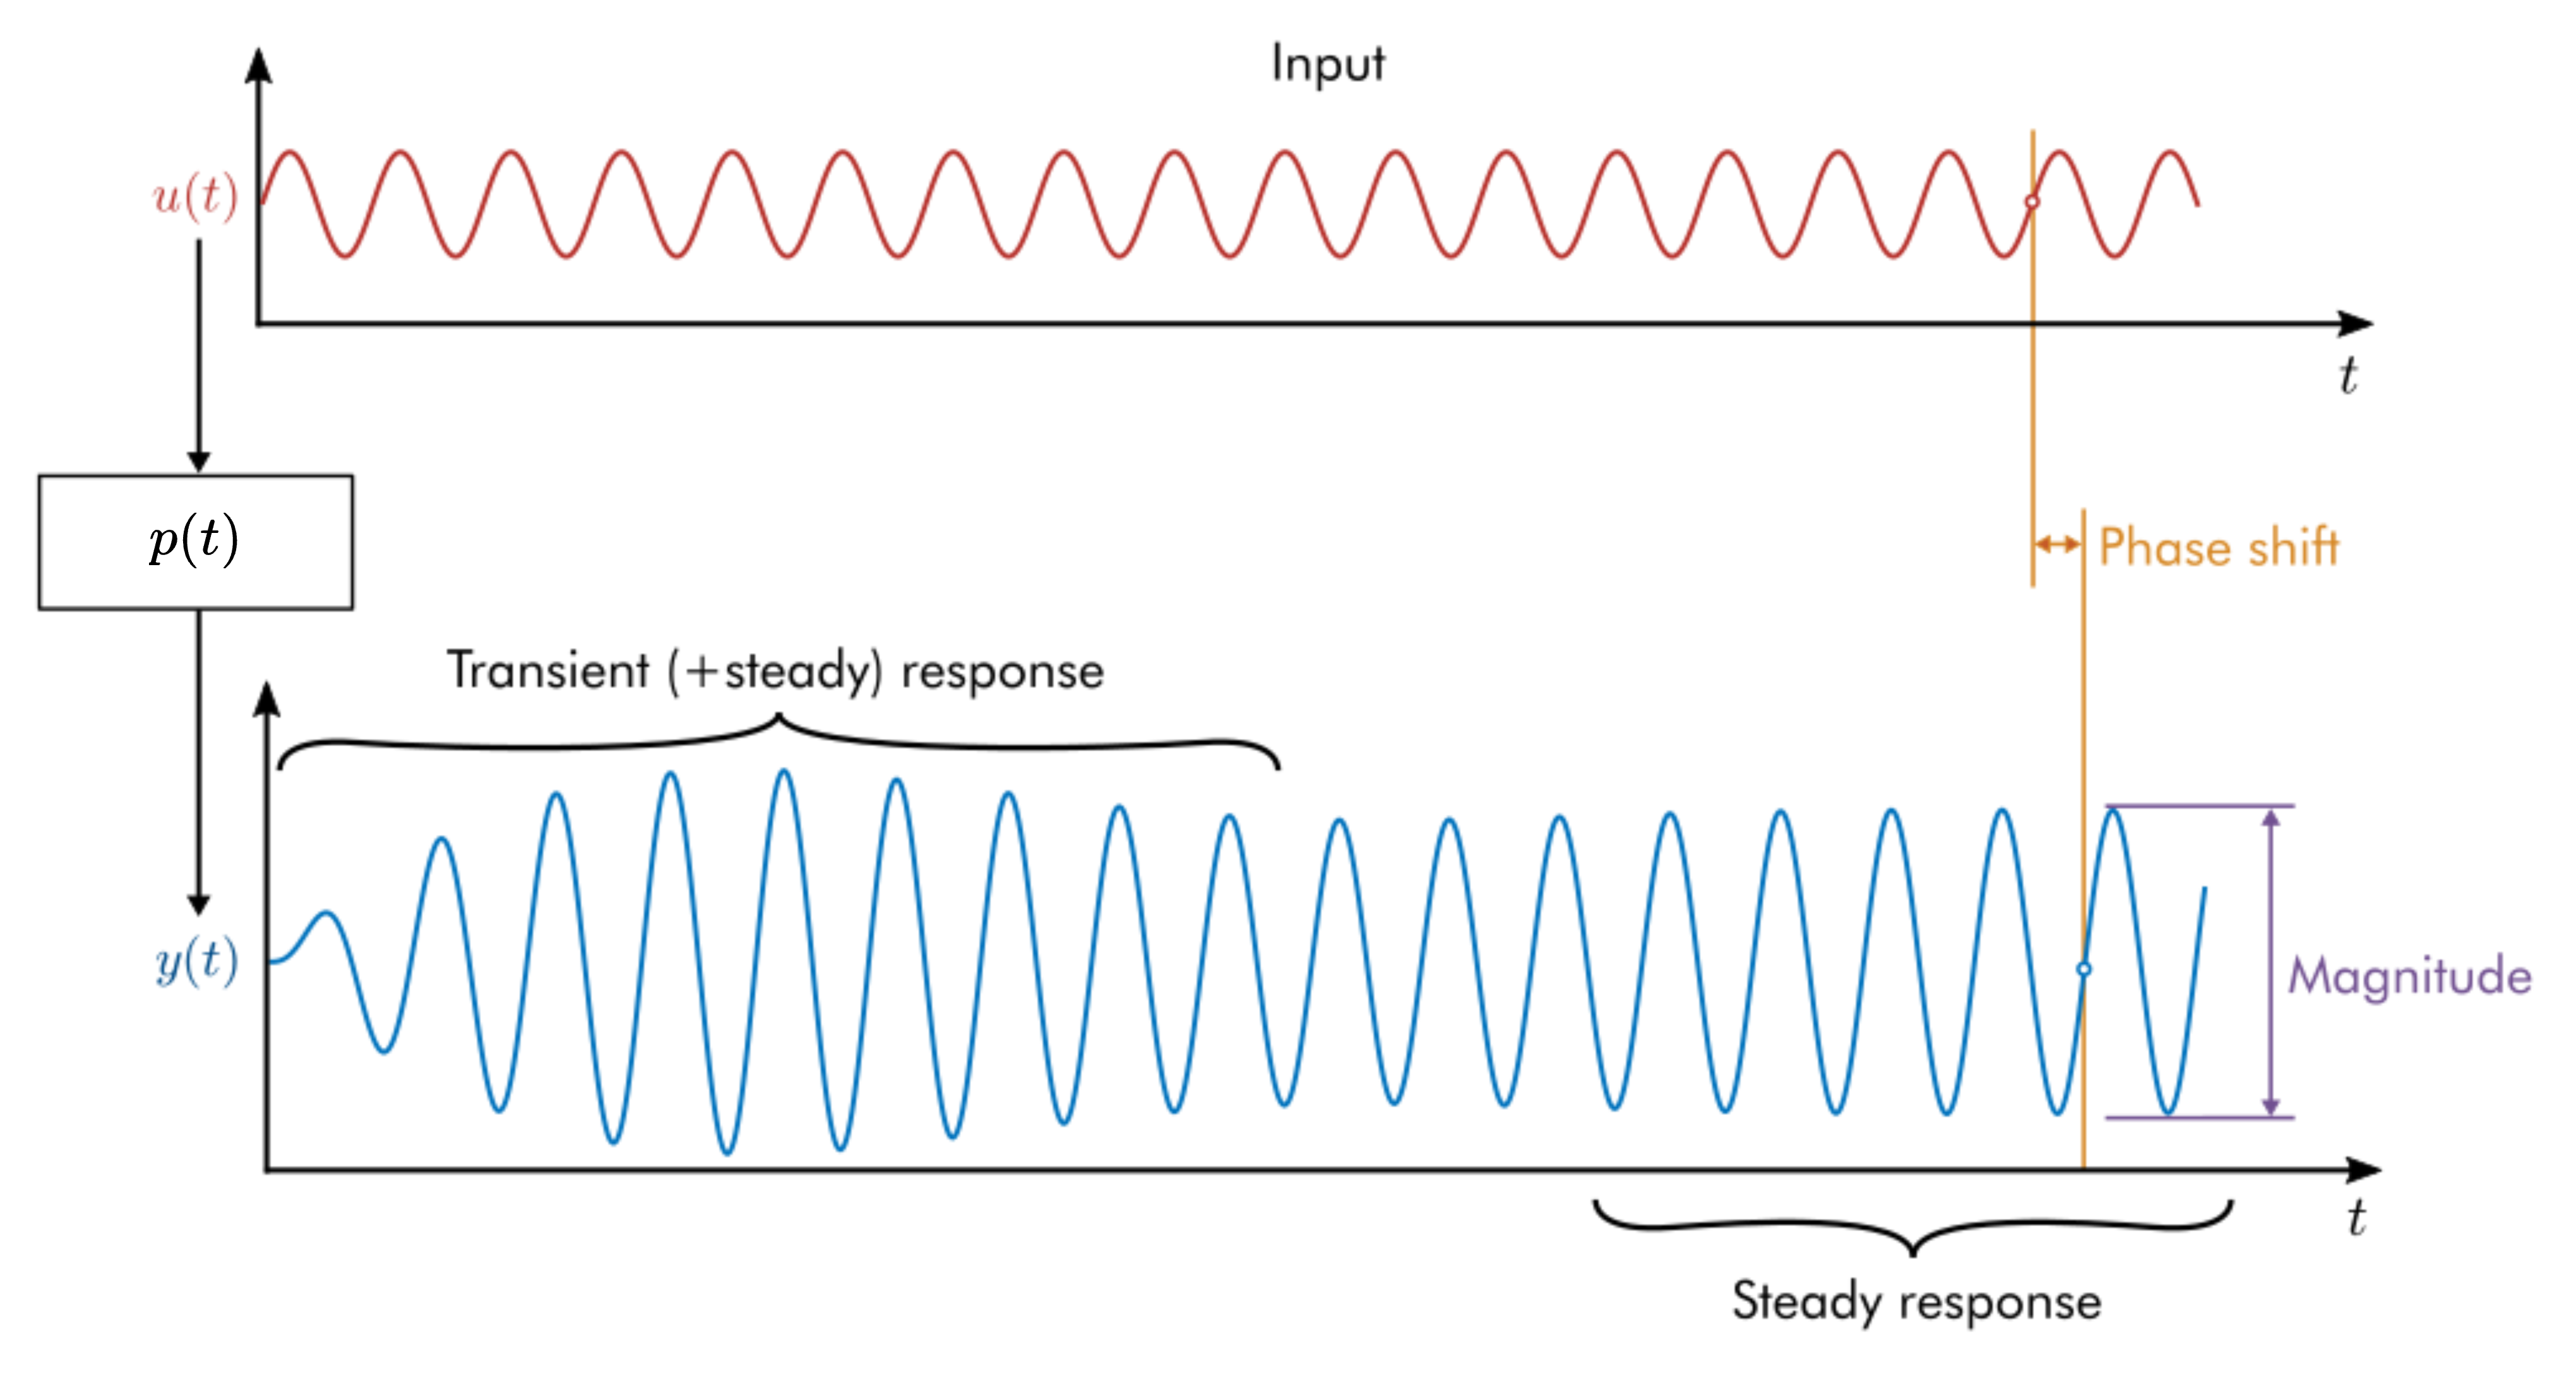

While not yet obvious, the frequency response contains invaluable information that we will use to conduct closed-loop analysis and control design in later chapters. The following section provides a formal derivation of the frequency response.

### 7.2.2 Deriving the frequency response

Consider an input signal in the form of a cosinusoid with unit amplitude,

$u(t)=\sin(\omega t)$.

The corresponding Laplace transformed signal is given as

$U(s)=\frac{\omega}{s^2+\omega^2}$.

Applying our sinusoidal input signal to system $P(s)$ results in an output response of

$Y(s)=P(s)U(s)=P(s)\frac{\omega}{s^2+\omega^2}$.

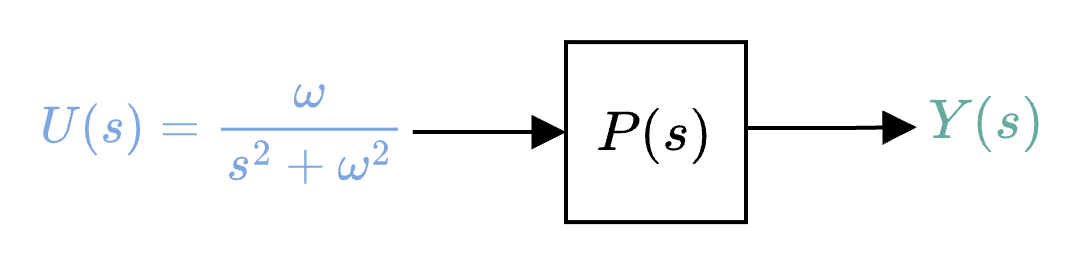

Using partial fraction expansion, the output response can be represented as


$$\begin{array}{rl}
Y(s)
&=P(s)\frac{\omega}{s^2+\omega^2},\\
&=P(s)\frac{\omega}{(s+j\omega)(s-j\omega)},\\
&=\frac{A}{s+j\omega}+\frac{B}{s-j\omega}+\text{Partial fraction terms from } P(s).
\end{array}$$


Using the residual formula we can determine $A$ and $B$ using

$A = \lim_{s\rightarrow -j\omega}\frac{\omega}{s-j\omega}P(s)=\frac{jP(-j\omega)}{2}$,

$B = \lim_{s\rightarrow j\omega}\frac{\omega}{s+j\omega}P(s)=\frac{-jP(j\omega)}{2}$.

At steady-state, when the natural response tends to zero (assuming the system is stable), the steady-state output response (made up only of the forced response) can be written as


$$\begin{array}{rl}
Y_{ss}(s)
&=\frac{A}{s+j\omega}+\frac{B}{s-j\omega},\\
&=\frac{jP(-j\omega)/2}{s+j\omega}-\frac{jP(j\omega)/2}{s-j\omega},\\
&=\frac{j\frac{M_P}{2}e^{-j\phi_P}}{s+j\omega}-\frac{j\frac{M_P}{2}e^{j\phi_P}}{s-j\omega},\\
&=\frac{\frac{M_P}{2}e^{-j(\phi_P-\pi/2)}}{s+j\omega}+\frac{\frac{M_P}{2}e^{j(\phi_P-\pi/2)}}{s-j\omega},\\
\end{array}$$


where $M_P(\omega) = |P(j\omega)|$, and $\phi_P(\omega)=\angle P(j\omega) = \tan^{-1}P(j\omega)$. Note that, strictly speaking, we should use `atan2` instead of $\tan^{-1}$. The steady-state time-domain output response can be determined using $y_{ss}(t)=\mathcal{L}^{-1}\{Y_{ss}(s)\}$, which yields


$$\begin{array}{rl}
y_{ss}(t)
&=\frac{M_P(\omega)}{2}e^{-j(\omega t+\phi_P(\omega)-\pi/2)}+\frac{M_P(\omega)}{2}e^{j(\omega t+\phi_P(\omega)-\pi/2)},\\
&={M_P(\omega)}\cos\left[\omega t+\phi_P(\omega)-\pi/2\right],\\
&={M_P(\omega)}\sin\left[\omega t+\phi_P(\omega)\right].
\end{array}$$


The sinusoidal output response at steady-state is therefore determined by scaling the input sinusoid of $u(t)=\sin(\omega t)$ by the plant magnitude $M_P(\omega)$, and adjusting the phase of the input sinusoid by the plant phase angle, $\phi_P(\omega)$.

In general, it may be shown that if the input sinusoid has a magnitude of $M_U$ and phase shift of $\phi_U$, namely

$u(t)=M_U\sin(\omega t+\phi_U)$,

 then the output response at steady-state follows as


$$\begin{array}{rl}
y_{ss}(t)
&={M_P(\omega)M_U}\sin\left[\omega t+\phi_P(\omega)+\phi_U\right],\\
&={M_Y(\omega)}\sin\left[\omega t+\phi_Y(\omega)\right],
\end{array}$$


where

$M_Y(\omega)=M_P(\omega)M_U$, 

and

$\phi_Y(\omega)=\phi_P(\omega)+\phi_U$.

As with the case when $u(t)=\sin(\omega t)$, the plant dynamics will scale the input sinusoid by $M_P(\omega)$, and shift the response by $\phi_P(\omega)$. Based on the above equations, we can also determine the magnitude and phase behaviour of our plant using

$M_P(\omega)=\frac{M_Y(\omega)}{M_U}$,

and 

$\phi_P(\omega)=\phi_Y(\omega)-\phi_U$,

respectively. $M_P(\omega)$ is referred to as the **magnitude response** of $P(s)$, and $\phi_P(\omega)$ is referred to as the **phase response**. Recall that we determined the magnitude and phase response using  $M_P(\omega) = |P(j\omega)|$, and $\phi_P(\omega)=\angle P(j\omega) = \tan^{-1}P(j\omega)$. The term $P(j\omega)$ therefore inherently contains the magnitude and phase response information that we are interested in. As such, the important result that we will make use of for the remainder of this course is that the **frequency response** of any stable system is determined by evaluating $P(s)$ as the Laplace operator, $s$, tends to infinity,

$P(j\omega)=M_P(\omega)e^{j\phi_P(\omega)}=\lim_{s\rightarrow j\omega}P(s)$.

#### Example 1

*Determine the magnitude response and phase response of *$P(s)=\frac{5}{s}$.

By definition, 

$P(j\omega)=\lim_{s\rightarrow j\omega}P(s)=\frac{5}{j\omega}=-\frac{5}{\omega}j$.

The frequency response will then have a magnitude response of $M_P(\omega)=|P(j\omega)|=\frac{5}{\omega}$, and a phase response of $\phi_P(\omega)=\angle P(j\omega)=-\frac{\pi}{2}$.

#### Example 2

*Determine the magnitude response, and phase response of *$P(s)=\frac{1}{s+10}$.

By definition, 

$P(j\omega)=\lim_{s\rightarrow j\omega}P(s)=\frac{1}{j\omega+10}$.

The frequency response will then have a magnitude response of 

$M_P(\omega)=|P(j\omega)|=\frac{1}{|j\omega+10|}=\frac{1}{\sqrt{\omega^2+100}}$, 

and a phase response of 

$\phi_P(\omega)=\angle P(j\omega)=\angle\{ \frac{1}{j\omega+10}\} = -\angle\{j\omega+10\}=-\tan^{-1}\frac{\omega}{10}$.

### 7.2.3 Frequency response of interconnected systems

The result above can be extended to systems that are interconnected in *any* linear configuration. This is important in control systems, as we usually have mulitple subsystems that are connected in various configurations, such as cascaded and parallel form. Regardless of the configuration, we can use $P(j\omega)=\lim_{s\rightarrow j\omega}P(s)$ to determine the system frequency response.

#### Cascaded form

Consider a cascaded system of 

$L(s)=P(s)G(s)$. 

The corresponding frequency response, $L(j\omega)$, follows as

$L(j\omega)=\lim_{s\rightarrow j\omega}P(s)G(s)=\lim_{s\rightarrow j\omega}P(s)\lim_{s\rightarrow j\omega}G(s)=P(j\omega)G(j\omega)$.

#### Parallel form

Consider the parallel configuration of 

$P(s)=P_1(s)+P_2(s)$. 

The corresponding frequency response, $P(j\omega)$, follows as

$P(j\omega)=\lim_{s\rightarrow j\omega}P_1(s)+P_2(s)=\lim_{s\rightarrow j\omega}P_1(s)+\lim_{s\rightarrow j\omega}P_2(s)=P_1(j\omega)+P_2(j\omega)$.

#### Feedback form

Consider the feedback form of 

$T(s)=\frac{P(s)G(s)}{1+P(s)G(s)}$.

The corresponding frequency response, $T(j\omega)$, follows as

$T(j\omega)=\lim_{s\rightarrow j\omega}\frac{P(s)G(s)}{1+P(s)G(s)}=\frac{\lim_{s\rightarrow j\omega}P(s)\lim_{s\rightarrow j\omega}G(s)}{1+\lim_{s\rightarrow j\omega}P(s)\lim_{s\rightarrow j\omega}G(s)}=\frac{P(j\omega)G(j\omega)}{1+P(j\omega)G(j\omega)}$.

### 7.2.4 Systems with time delay

Recall that time delay in the time domain can be related to the Laplace domain based on

$\mathcal{L}\{f(t-\tau)\} =\mathcal{L}\{ f(t)\}e^{-s\tau}=  F(s)e^{-s\tau}$.

Based on this, a system with delay is represented in the Laplace domain as

$P(s)=\hat{P}(s)e^{-s\tau}$.

The frequency response of $P(s)$ follows as


$$P(j\omega)=\hat{P}(j\omega)e^{-j\omega\tau}$$


We can evaluate the magnitude response of the system using

$|P(j\omega)|=|\hat{P}(j\omega)||e^{-j\omega\tau}|=|\hat{P}(j\omega)|$,

where $|e^{-j\omega\tau}|=1$. Based on this result, the time delay does not affect the magnitude response.

The phase response of the system is determined by

$\angle P(j\omega)=\angle \hat{P}(j\omega)e^{-j\omega\tau}=\angle \hat{P}(j\omega)+\angle e^{-j\omega\tau}=\angle \hat{P}(j\omega)-\omega\tau$.

Based on this, the time delay reduces the phase response of $P(j\omega)$ as a function of $\omega$. Specifically, time delay induces *phase lag* that increases linearly based on the frequency. An example is shown using the code below.

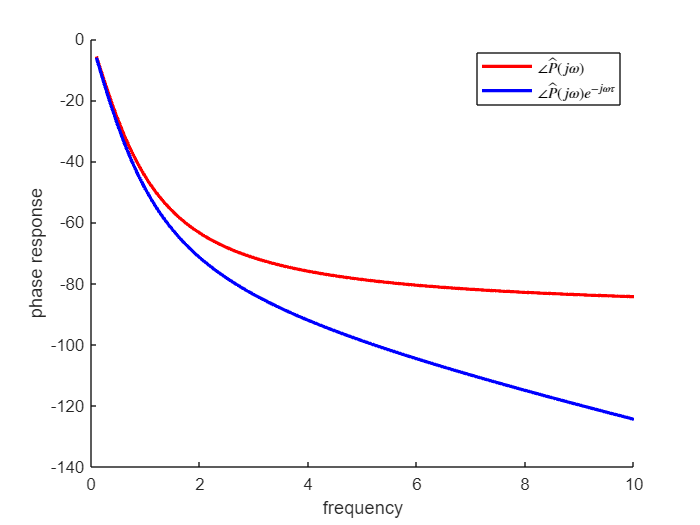

%Example
s = tf('s');

tau = 0.07;

P_hat = 1/(1+s);
P = P_hat*exp(-s*tau);

W = linspace(0.1,10,1000);

Pw_hat = squeeze(freqresp(P_hat,W));
Pw = squeeze(freqresp(P,W));

Pw_hat_angle = unwrap( angle( Pw_hat ) )*180/pi;
Pw_angle = unwrap( angle( Pw ) )*180/pi;

figure, hold on
plot(W,Pw_hat_angle,'r',lineWidth=2)
plot(W,Pw_angle,'b',lineWidth=2)
xlabel('frequency'),ylabel('phase response')
legend('$\angle \hat{P}(j\omega)$','$\angle \hat{P}(j\omega)e^{-j\omega\tau}$',Interpreter='latex')

### 7.2.5 Understanding the frequency response

The frequency response describes the gain and phase behaviour of the system under consideration. The magnitude response (or gain), $|P(j\omega)|$, tells us how input signals are amplified/reduced when passing through the system, and the phase response, $\angle P(j\omega)$, tells us how output signal will lead or lag the input signal. We can use this information to understand the input-output relationship between signals in the frequency domain. For example, if a reference signal is defined as $R(s)=\sin(2t)$, and we would ideally like the output to match the reference, ie $Y(s)=R(s)$, then we would want the frequency response to be equal to one with zero phase response at $\omega=2$ rad/s, namely $P(j2)=1$. However, consider the system of $P(s)=\frac{1}{s+10}$, which has a magnitude and phase response of $|P(j\omega)|=\frac{1}{\sqrt{\omega^2+100}}$, and$\angle P(j\omega)=-\tan^{-1}\frac{\omega}{10}$, respectively. Evaluating the magnitude and phase response at $\omega=2$ rad/s yields 

$|P(j2)|=\frac{1}{\sqrt{4+100}}=0.098$, 

and 

gain $\angle P(j\omega)=\tan^{-1}\frac{2}{10}=-0.197$ rad.

In other words, the output response, after the natural response has died out, will be smaller in amplitude than $r(t)=\sin(2t)$ by a factor of $0.098$, and will delay the input signal by $0.197$ radians (or $11.31^\circ$). The code block below can be used to show the input and output behaviour of the system, which confirms the mathematical interpretation of the frequency response.

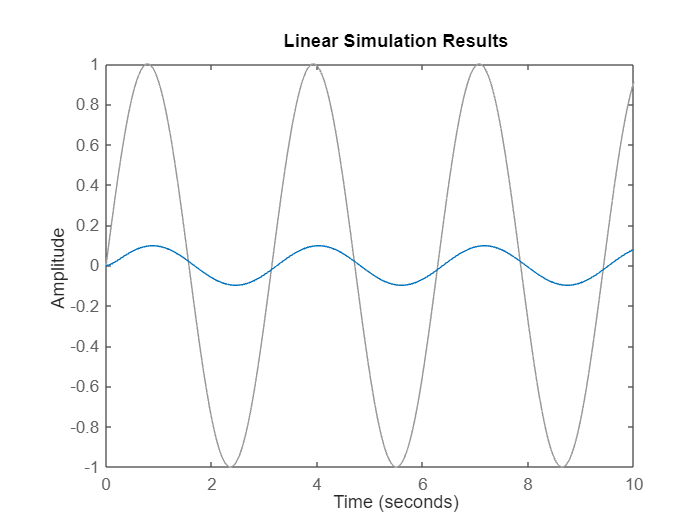

clear
s = tf('s');
P = 1/(s+10);

t = linspace(0,10,1e6);
r = sin(2*t);

figure
lsim(P,r,t);

In later chapters, we will exploit the concept of frequency response in order to design closed-loop systems that have a magnitude response of approximately one for the realistic frequencies of interest, whilst also reducing the phase lag at these frequencies. By doing so, we will be able to achieve good reference tracking ($y(t)\approx r(t)$) within the specified frequency band.

## 7.3 Visualising frequency response

Based on the previous section, we can determine the frequency response using

$P(j\omega)=\lim_{s\rightarrow j\omega}P(s)$,

which means that we are simply swapping $'s'$ terms in the transfer function with $'j\omega'$ terms. The frequency response can be thought of simply as a complex number at every frequency point, $\omega$, which has the representation of 

    $P(j\omega)=a(\omega)+jb(\omega)$.

This is commonly referred to as the rectangular form.

%Example
s = tf('s');
P = ((s+3)*(s+5))/(s*(s+2)*(s+4))

P =
 
   s^2 + 8 s + 15
  -----------------
  s^3 + 6 s^2 + 8 s
 
Continuous-time transfer function.
Model Properties



W = 1;
Pw = frd(P,W) %frequency response of P(s) for omega=1:10;

Pw =
 
    Frequency(rad/s)         Response    
    ----------------         --------    
            1           -0.3294 - 1.7176i
 
Static gain.
Model Properties


As shown in the previous section, we can also represent $P(j\omega)$ in polar form

$P(j\omega)=|P(j\omega)|e^{\angle P(j\omega)}=M_P(\omega)e^{ \phi_P(\omega)}$,

where the polar form is related to the rectangular form using

$|P(j\omega)|=\sqrt{a^2(\omega)+b^2(\omega)}$,

and

$\angle P(j\omega) = \tan^{-1}\left(\frac{b(\omega)}{a(\omega)}\right)$.

P_mag = abs(Pw) %magnitude response of P

P_mag =
 
    Frequency(rad/s)    Response
    ----------------    --------
            1            1.7489 
 
Static gain.
Model Properties


P_angle = angle(Pw) %phase response of P

P_angle =
 
    Frequency(rad/s)    Response
    ----------------    --------
            1            -1.7603
 
Static gain.
Model Properties


The frequency response will be able to provide us with important information about the system under consideration. The easiest approach to interpret information from the frequency response is to plot the information in a way that allows for easy understanding of the system behaviour. The following sections present three common approaches to visualising the frequency response, namely

- Nyquist diagrams

- Bode diagrams

- Log-polar plots

### 7.3.1 Nyquist diagram

An arithmetic approach to plotting the frequency response is to use the (arithmetic) complex plane, where the real and imaginary components of the frequency response are plotted for each frequency, running from $\omega=0$, to $\omega\rightarrow\infty$ using the rectangular form of

    $P(j\omega)=a(\omega)+jb(\omega)$.

In control theory this is referred to as a **Nyquist diagram**, as shown below. Note that is not the same plane as the s-plane!

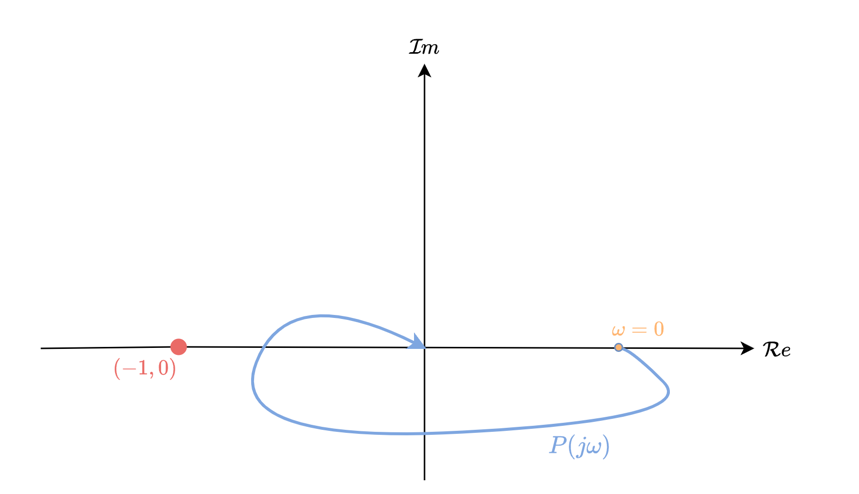

The Nyquist diagram will be useful in future chapters in terms of formalising stability and performance metrics.

#### Example

The Nyquist diagram of $L(s) = \frac{1}{1+s}$ can be plotted by first generating the frequency response of $L(s)$ in arithmetic form at a suitable range of frequency points. We begin by determining $L(j\omega)=a(j\omega)+jb(\omega)$, which can be found to be

$L(j\omega)=\frac{1}{1+j\omega}\frac{1-j\omega}{1-j\omega}=\frac{1-j\omega}{1+\omega^2}=\frac{1}{1+\omega^2}-j\frac{\omega}{1+\omega^2}$.

If we now evaluate $L(j\omega)$ for any $\omega\geq 0$, then we can determine the corresponding complex number and then plot it in the complex plane. We can do this by hand if we want, but its easier to let a software package to this for us.

clear
s = tf('s');
L = 1/(1+s);
W = linspace(0,1000,1e5);
Lw = squeeze( freqresp(L,W) );

At this point, we could then sketch out the frequency response locus, starting from $\omega=0$ rad/s, all the way to $\omega=1000$ rad/s. Again, it is easier to let MATLAB do the mundane work for us, as shown below.

figure,hold on
plot(real(Lw),imag(Lw),'-b')
for i=1:50:501
    plot(real(Lw(i)),imag(Lw(i)),'ok',MarkerFaceColor='k')
    text(real(Lw(i)),imag(Lw(i)),['  \omega= ',num2str(W(i),2)])
end
xlabel('Real axis')
ylabel('Imaginary axis')

The Nyquist diagram will now present information about $L(j\omega)$ in a way that is easier to interpret. For example, we can calculate $L(j0)$ using our equation, or simply read it off the Nyquist diagram. The profile of the Nyquist locus will also provide us with useful stability information in later chapters. Note that we need to label the locus with the relevant frequency values, otherwise we would lose insight into the frequency dependence of the frequency response.

### 7.3.2 Bode diagram

A common means of visualising the magnitude and phase response of $P(s)$ is to plot $|P(j\omega)|$ and $\angle P(j\omega)$ separately against frequency. As we will show shortly, there is benefit in plotting the magnitude of $P(j\omega)$ in decibels (dB) vs logarithmic frequency ($\log \omega$). In the case of the phase response we plot phase angle (in degrees) vs $\log \omega$. This type of plot is known as a **Bode diagram**, as shown below.

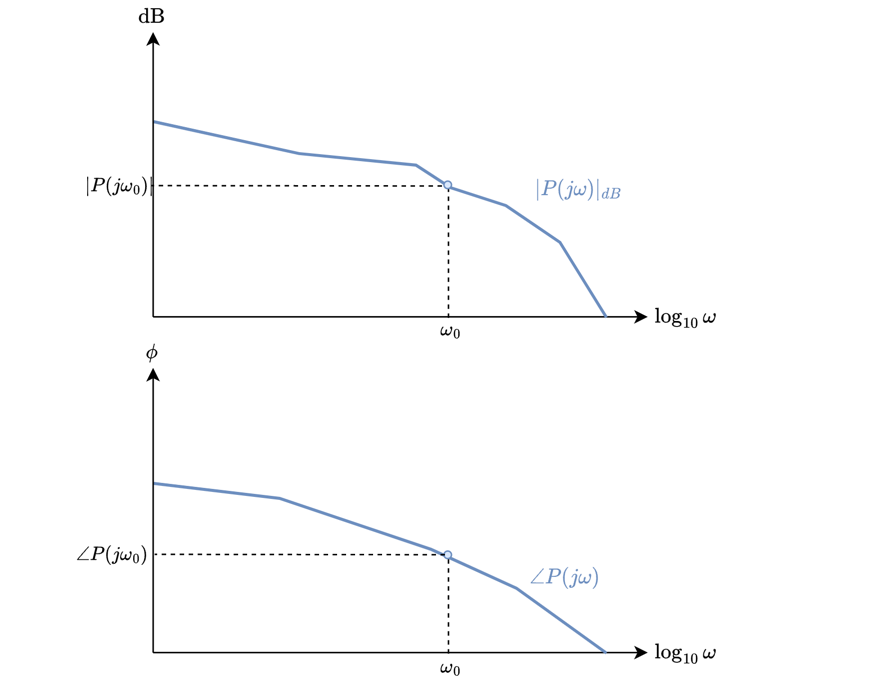

We determine the *logarithmic* magnitude using

$|P(j\omega)|_{db}=20\log_{10}|P(j\omega)|$.

The phase response of $P(j\omega)$, plotted in degrees, is determined using 

$\angle P(j\omega)=\tan^{-1}\left( \frac{b(\omega)}{a(\omega)}\right)\frac{180}{\pi}$.

The decibel representation is useful as we can exploit the following logarithmic identities:


$$\log_{10}(AB)=\log_{10}A+\log_{10}B$$



$$\log_{10}(A/B)=\log_{10}A-\log_{10}B$$


In other words, multiplication in *arithmetic* units is equivalent to addition in *logarithmic* units. This extends to any number of product or division operations. Similarly, because multiplication by a complex number is equivalent to a rotation and scaling, we can use the following identities when determining phase angle:


$$\angle \{c(j\omega)d(j\omega)\}=\angle c(j\omega) + \angle d(j\omega)$$



$$\angle \{c(j\omega)/d(j\omega)\}=\angle c(j\omega) - \angle d(j\omega)$$


This extends to any number of product or division operations.

#### Example

The Bode diagram of $L(s) = \frac{1}{1+s}$ can be determined by first generating the frequency response of $L(s)$ in magnitude-phase form, at a suitable range of frequency points. We begin by determining $L(j\omega)=|L(j\omega)|e^{\phi_L(\omega)}$, which can be found to be

$|L(j\omega)|=|\frac{1}{1+j\omega}|=\frac{1}{|1+j\omega|}=\frac{1}{\sqrt{1+\omega^2}}$,

$\angle L(j\omega)={\angle\{\frac{1}{1+j\omega}\}}={-\angle\{1+j\omega\}}=-\tan^{-1}\omega$.

The logarithmic magnitude and phase response (in degrees) follow as

$|L(j\omega)|_{dB}=20\log_{10}\frac{1}{\sqrt{1+\omega^2}}=-20\log_{10}{\sqrt{1+\omega^2}}$,

$\angle L(j\omega)=-\frac{180}{\pi}\tan^{-1}\omega$.

If we now evaluate $|L(j\omega)|_{dB}$ and $\angle L(j\omega)$ for any $\omega\geq 0$, then we can determine the corresponding logarithmic magnitude response and phase response, and then plot them against logarithmic frequency, $\log_{10}\omega$. We can do this by hand if we want, but its easier to let a software package to this for us.

%Example
s = tf('s');
L = 1/(1+s);

figure, hold on
bode(L)
grid on

We can then easily read information about the frequency response from the Bode diagram, such as the magnitude and phase response at $\omega=10$ rad/s.

A benefit of the logarithmic scale is that if we multiply $L(s)$ by some gain, $k$, then the resulting logarithmic magnitude response of $kL(s)$ will simply be equal to the logarithmic magnitude response of $L(s)$, plus the logarithmic magnitude response of $k$, based on our logarithmic identity, namely

$20\log_{10}(|k||L(j\omega)|)=20\log_{10}|k|+20\log_{10}(|L(j\omega)|)$.

When plotted in the Bode diagram, this scaling of $k$ can be visualised by shifting the logarithmic magnitude response of $L(s)$, across all frequencies, up/down by $20\log_{10}|k|$, depending on the value of $k$.

clear
s = tf('s');
L = 5*(s+10)/s/(1+s)^2;

k = 1.5;
k_dB = 20*log10(k)

figure, hold on
bodemag(L)
bodemag(k*L)
grid on
legend('$|L(j\omega)|$','$|kL(j\omega)|$',Interpreter='latex')

Note that 

- $20\log_{10}|k|>0$ for $|k|>1$, 

- $20\log_{10}|k|<0$ for $|k|<1$, and 

- $20\log_{10}|k|=0$ for $|k|=1$.

As such, the graph will shift up when $|k|>1$, shift downwards when $|k|<1$, and remain unchanged when $|k|=1$.

### 7.3.3. Log-polar plot

The **log-polar plot** is an extension of the Bode diagram that compares logarithmic magnitude against phase angle (in degrees) directly, namely $|P(j\omega)|_{db}$ vs $\angle P(j\omega)$, as shown below. 

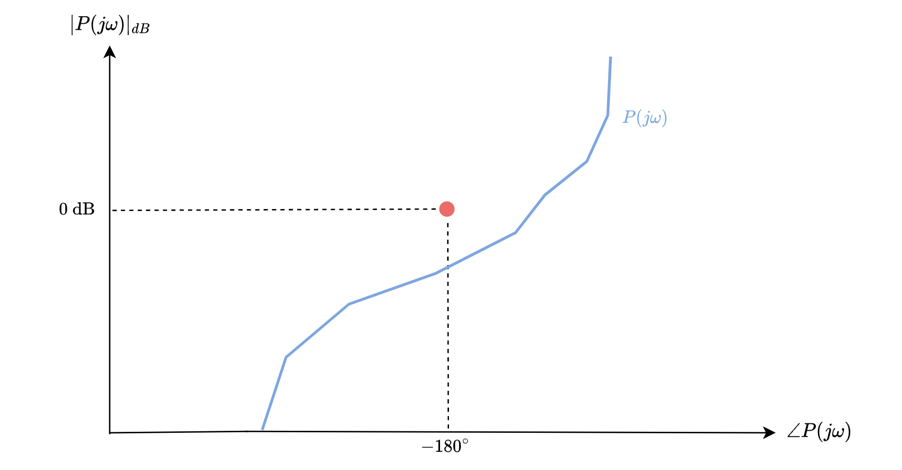

Like the Bode diagram, multiplicate gain adjustment of $L(s)$ results in the log-polar frequency response locus being shifted up or down, depending on the value of the gain. Similarly, the graph will shift left/right depending on the phase lead/lag added to the system. We will exploit this behaviour in later chapters to design feedback controllers that can meet performance specifications.

#### Example

The Log-polar plot of $L(s) = \frac{1}{1+s}$ can be determined by first generating the frequency response of $L(s)$ in magnitude-phase form (as with the Bode diagram), at a suitable range of frequency points. We begin by determining $L(j\omega)=|L(j\omega)|e^{\phi_L(\omega)}$, which can be found to be

$|L(j\omega)|=|\frac{1}{1+j\omega}|=\frac{1}{|1+j\omega|}=\frac{1}{\sqrt{1+\omega^2}}$,

$\angle L(j\omega)={\angle\{\frac{1}{1+j\omega}\}}={-\angle\{1+j\omega\}}=-\tan^{-1}\omega$.

The logarithmic magnitude and phase response (in degrees) follow as

$|L(j\omega)|_{dB}=20\log_{10}\frac{1}{\sqrt{1+\omega^2}}=-20\log_{10}{\sqrt{1+\omega^2}}$,

$\angle L(j\omega)=-\frac{180}{\pi}\tan^{-1}\omega$.

If we now evaluate $|L(j\omega)|_{dB}$ and $\angle L(j\omega)$ for any $\omega\geq 0$, then we can determine the corresponding logarithmic magnitude response and phase response, and then plot them against eachother in the log-polar plot. We can do this by hand if we want, but its easier to let a software package to this for us.

%Example
s = tf('s');
L = 1/(1+s);

figure, hold on
nichols(L)


Similar to the Nyquist plot, we need to also indicate the particular frequency points on the log-polar plot, which we can do using the code below.

W = linspace(0,1000,1e5);
Lw = squeeze( freqresp(L,W) );

Lw_mag = 20*log10(abs(Lw));
Lw_phase = angle(Lw)*180/pi;

for i=1:50:501
    plot(Lw_phase(i),Lw_mag(i),'ok',MarkerFaceColor='k')
    text(Lw_phase(i),Lw_mag(i),['  \omega= ',num2str(W(i),2)])
end

As with the Nyquist diagram and Bode diagram, we can easily read off gain and phase behaviour of the system when using a log-polar plot. What we should also notice is that all three diagrams (Nyquist, Bode, log-polar) are equivalent in terms of the information they present, and it would not be unreasonable to convert the information from one diagram to another.

A benefit of the logarithmic scale is that if we multiply $L(s)$ by some gain, $k$, then the resulting logarithmic magnitude response of $kL(s)$ will simply be equal to the logarithmic magnitude response of $L(s)$, plus the logarithmic magnitude response of $k$, based on our logarithmic identity, namely

$20\log_{10}(|k||L(j\omega)|)=20\log_{10}|k|+20\log_{10}(|L(j\omega)|)$.

When plotted in a log-polar diagram, this scaling of $k$ can be visualised by shifting the frequency response locus of $L(s)$, across all frequencies, up/down by $20\log_{10}|k|$, depending on the value of $k$.

clear
s = tf('s');
L = 5*(s+10)/s/(1+s)^2;

k = 2;
k_dB = 20*log10(k)




figure, hold on
nichols(L)
nichols(k*L)
legend('$|L(j\omega)|$','$|kL(j\omega)|$',Interpreter='latex')

## 7.4 Frequency response via testing

Similar to the method of examining the step response of an unknown system in order to characterise the plant dynamics, the frequency response methodology can be used to characterise the system, albeit in the frequency domain. Specifically, if the system under consideration is stable, then one can individually apply sinusoids of different frequencies to a system input and then measure the corresponding system outputs at steady state. If the set of all input and steady-state output sinusoids are then logged and compared, the difference in magnitude and phase between the input and output signals, across all frequencies, will then collectively describe the frequency response.

The following code below simulates the response of the system 


$$P(s)=\frac{1}{s^2+s+1}$$


to sinusoidal inputs of different frequencies. The black boxes on the Bode plots indicate how the steady-state output should be scaled and shifted for a sinusoidal input of the specificied frequency, $\omega_u$. As we are only interested in the steady-state response when assessing frequency response, the output response shown below has truncated the output response to only show the periodic behaviour (at steady-state).

clear
s = tf('s');
P = 1/(s^2 + 1*s + 1);                %Our second-order system

omega_u =1.23;      %Input sinusoid frequency in rad/s
t = 0:0.1:120;                          %Time vector
u = sin(omega_u*t);                      %Input sinusoid
[y,t] = lsim(P,u,t);                    %Use lsim to generate output response
f3 = figure;
subplot(1,2,1)
subplot(1,2,2)                          %Plot two figures in parallel
[gain,phi] = bode(P,omega_u)              %Get frequency response of P at omega_u

bode(P,omega_u,'ks')                     %Plot black box on bode diagram.
grid
hold on;                                %Hold figure so that subsequent plots dont clear figure
bode(P,{0.1,10});                       %Plot frequency response for w=0.1 rad/s to w=10 rad/s
subplot(1,2,1)
plot(t,u,'r',t,y,'b')                   %Plot time-domain input and output signals
legend('$u(t)$','$y(t)$',Interpreter='latex')
grid
axis([80 t(end) -10 10])
clf(f3)

## 7.5 System characteristics from the frequency response

### 7.5.1 DC gain

The **DC (or steady-state) gain** of a system is defined as the magnitude response of the system when $\omega\rightarrow 0$. As the name suggests, we consider the gain of the system at DC conditions. This is formally defined as

$G_{dc}=\lim_{\omega\rightarrow 0}P(j\omega)=P(0)$.

Given that the frequency response is determined by setting $s=j\omega$, we can similarly determine the DC gain from a system represented as a transfer function using

$G_{dc}=\lim_{s\rightarrow 0}P(s)=P(0)$.

Note the similarity between DC gain of a system and final-value theorem when the input signal is a *unit step, *$U(s)=1/s$, namely $y_\infty=\lim_{s\rightarrow 0}sY(s)=\lim_{s\rightarrow 0}P(s)$. In general, when a step input, $u(t)=\beta$, is applied to a stable system, the DC gain of $P(s)$, multiplied by the input step $\beta$, will indicate the steady-state gain of the system, namely

$y_\infty=G_{dc}\beta$.

#### Example

*Determine the DC gain of *$P(s)=\frac{s+10}{s^2+5s+1}$.

The DC gain of $P(s)$ is determined as


$$G_{dc}=\lim_{s\rightarrow 0}P(s)=\lim_{s\rightarrow 0}\frac{s+10}{s^2+5s+1}=10.$$


This implies that if a step input is applied to $P(s)$, the steady-state output response will be $10$ times larger than the input signal. This can be shown using the code below.

clear
s = tf('s');
P = (s+10)/(s^2+5*s+1);

b = 1;
[y,t] = step(P*b);

figure, hold on
plot(t,b*ones(size(t)),lineWidth=2)
plot(t,y,lineWidth=2)
legend('u(t)','y(t)')

### 7.5.2 High-frequency gain

The **high-frequency gain** of a system is defined as the magnitude response of the system when $\omega\rightarrow \infty$. As the name suggests, we consider the gain of the system at high frequencies. This is formally defined as

$G_{hf}=\lim_{\omega\rightarrow \infty}P(j\omega)=P(\infty)$.

Given that the frequency response is determined by setting $s=j\omega$, we can similarly determine the high-frequency gain from a system represented as a transfer function using

$G_{hf}=\lim_{s\rightarrow \infty}P(s)=P(\infty)$.

Note the similarity between high-frequency gain and initial-value theorem when the input signal is a unit step, $U(s)=1/s$, namely $y(0)=\lim_{s\rightarrow \infty}sY(s)=\lim_{s\rightarrow \infty}P(s)$. In general, when a step input, $u(t)=\beta$, is applied to a stable system, the high-frequency gain of $P(s)$, multiplied by the input step $\beta$, will indicate the initial resposne of the system, namely

$y(0)=G_{hf}\beta$.

#### Example

*Determine the high-frequency gain of *$P(s)=\frac{s+10}{2s+5}$.

The high-frequency gain of $P(s)$ is determined as


$$G_{hf}=\lim_{s\rightarrow \infty}P(s)=\lim_{s\rightarrow \infty}\frac{s+10}{2s+5}=\frac{1}{2}.$$


Note that we made use of L'Hopitals rule to evaluate the limit. The result above implies that if a step input is applied to $P(s)$, the output response at $t=0$, $y(0)$, will be half the size of the step input value. This can be confirmed using the code below.

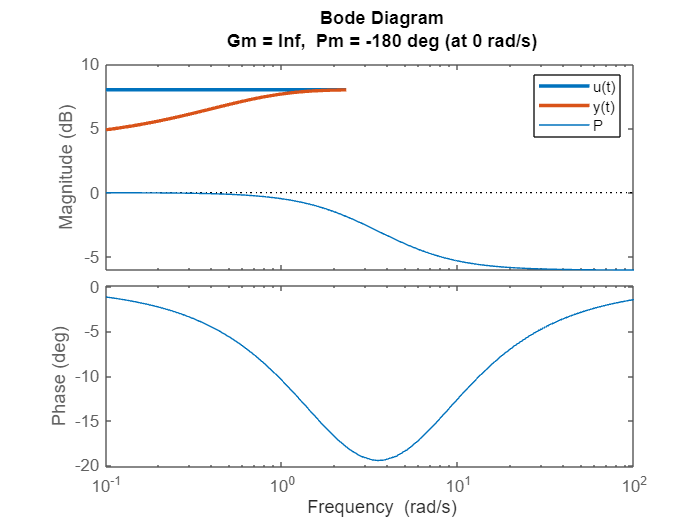

clear
s = tf('s');
P = (s+5)/(2*s+5);
margin(P)

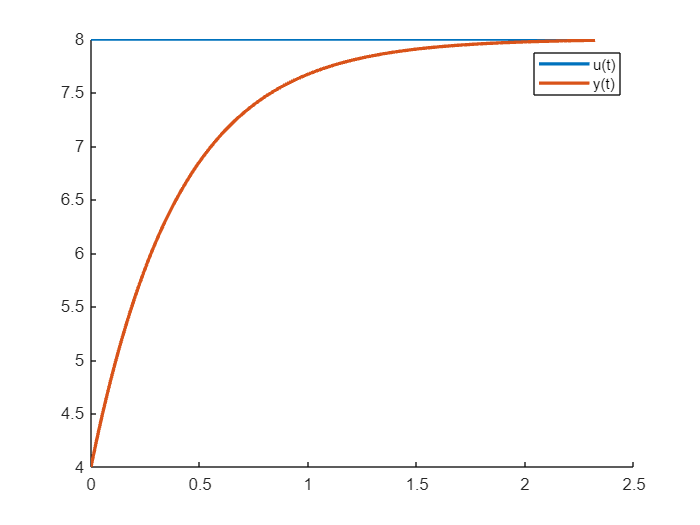

b = 8;
[y,t] = step(P*b);

figure, hold on
plot(t,b*ones(size(t)),lineWidth=2)
plot(t,y,lineWidth=2)
legend('u(t)','y(t)')

### 7.5.3 Number of integrators

The number of integrators in a system can be determined by consulting the frequency response at low frequencies. This is useful if the transfer function model is unknown, but the frequency response can be obtained via testing. Consider the factored transfer function below of

$P(s)=A_p\frac{\prod_{i=1}^m(s-z_i)}{s^k\prod_{i=1}^{n-k}(s-p_i)}$,

which contains $k$ integrators. The corresponding frequency response is given by

$P(j\omega)=A_p\frac{\prod_{i=1}^m(j\omega-z_i)}{(j\omega)^k\prod_{i=1}^{n-k}(j\omega-p_i)}$.

At sufficiently low frequencies of $\omega \ll \{|z_i|,|p_i|\}$, that is frequencies much smaller than the frequencies of all poles and zeros, the frequency response can be approximated as

$\left.P(j\omega) \approx A_p\frac{(-1)^{m-n}\prod_{i=1}^mz_i}{(j\omega)^k\prod_{i=1}^{n-k}p_i}$.

Based on the above result, the shape of the frequency response at sufficiently low frequencies will be dictated by the number of integrators in $P(s)$. The phase response of $P(j\omega)$ at low frequencies follows as

$\angle P(j\omega) = \angle\{ A_p\frac{(-1)^{m-n}\prod_{i=1}^mz_i}{(j\omega)^k\prod_{i=1}^{n-k}p_i}\}=-\angle\{(j\omega)^k\}=-90k^\circ$.

We can therefore determine the number of integrators, $k$, by consulting the phase response of $P(j\omega)$ at low frequencies.

#### Example

Consider the system $P(s)=\frac{s+5}{s^2(1+s/10)}$. Visualising the frequency response in a Bode diagram shows that the phase response at low frequencies tends to $-180^\circ$. Based on our result above that the phase response at sufficiently low frequencies will be equal to $-90k^\circ$ implies that our system has $k=2$ integrators.

clear
s = tf('s');
P = (s+5)/s^2/(1+s/10);
figure
bode(P)

We can also visualise this in a log-polar plot, for example, as shown using the code below.

figure
nichols(P)

### 7.5.4 Relative degree

Recall that the relative degree is defined as the difference between the number of poles, $n$, and zero, $m$, namely $n-m$. If we consider our factored system transfer function

$P(s)=A_p\frac{\prod_{i=1}^m(s-z_i)}{\prod_{i=1}^n(s-p_i)}$,

the phase response follows as

$\angle P(j\omega)=\angle\{A_p\frac{\prod_{i=1}^m(j\omega-z_i)}{\prod_{i=1}^n(j\omega-p_i)}\}=\angle\{{\prod_{i=1}^m(j\omega-z_i)\}-\angle\{\prod_{i=1}^n(j\omega-p_i)}\}$.

If we now find the phase angle of a zero as $\omega\rightarrow\infty$, we find that 

$\lim_{\omega\rightarrow\infty}\angle\{j\omega-z_i\}=\lim_{\omega\rightarrow\infty}\tan^{-1}\left(\frac{\omega}{-z_i}\right)=90^\circ$,

for $z_i<0$ (ie zeros in the OLHP). Similarly, each pole will contribute $-90^\circ$ of phase, based on

$\lim_{\omega\rightarrow\infty}-\angle\{j\omega-p_i\}=-\lim_{\omega\rightarrow\infty}\tan^{-1}\left(\frac{\omega}{-p_i}\right)=-90^\circ$,

for $p_i<0$. Therefore, assuming all $m$ zeros are located in the OLHP, the sum contribution of phase *lead* will be $90m^\circ$, and the sum contribution of phase *lag* from the poles will be $-90n^\circ$. The resulting phase response of $P(j\omega)$ as $\omega$ tends to infinity follows as

$\lim_{\omega\rightarrow\infty}\angle P(j\omega)=-90n^\circ+90m^\circ=-90(n-m)^\circ$.

We can therefore determine $n-m$ from a frequency response visualisation by assessing the phase response as $\omega\rightarrow\infty$.

#### Example

*Confirm that *$P(s)=\frac{s+5}{s^2(1+s/10)}$* has a relative degree of *$n-m=2$.

We can visualise the frequency response of $P(s)$ in a log-polar plot, for example, as shown using the code below.

clear
s = tf('s');
P = (s+5)/s^2/(1+s/10);
figure,hold on
nichols(P)
ylim([-120 60])

W = linspace(0,1000,1e3);
Pw = squeeze( freqresp(P,W) );

Pw_mag = 20*log10(abs(Pw));
Pw_phase = angle(Pw)*180/pi;

for i=[2,10,100,1000]
    plot(Pw_phase(i),Pw_mag(i),'ok',MarkerFaceColor='k')
    text(Pw_phase(i),Pw_mag(i),['  \omega= ',num2str(W(i),2)])
end

We observe that as $\omega$ tends to infinity, the phase response tends to $-180^\circ$. Based on our formula above of

$\lim_{\omega\rightarrow\infty}\angle P(j\omega)=-90n^\circ+90m^\circ=-90(n-m)^\circ$,

this means that our relative degree can be determined by solving

$-180=-90(n-m)^\circ$,

which yields $n-m=2$.

## 7.6 Common types of frequency response

### 7.6.1 First-order low-pass filter

As the name suggests, low-pass filters allow signals with sufficiently low frequencies to *pass* through unaltered, whereas high frequency signals become attenuated and delayed. The frequency response is an ideal way of visualising this behaviour. In the case of the low-pass filter, the *passband* is the band of frequencies from $[0,\omega_0]$, where signals are effectively passed, and the attenuation band describes all frequencies of $\omega>\omega_0$, where signals are effectively attenuated. An example of this is shown below. 

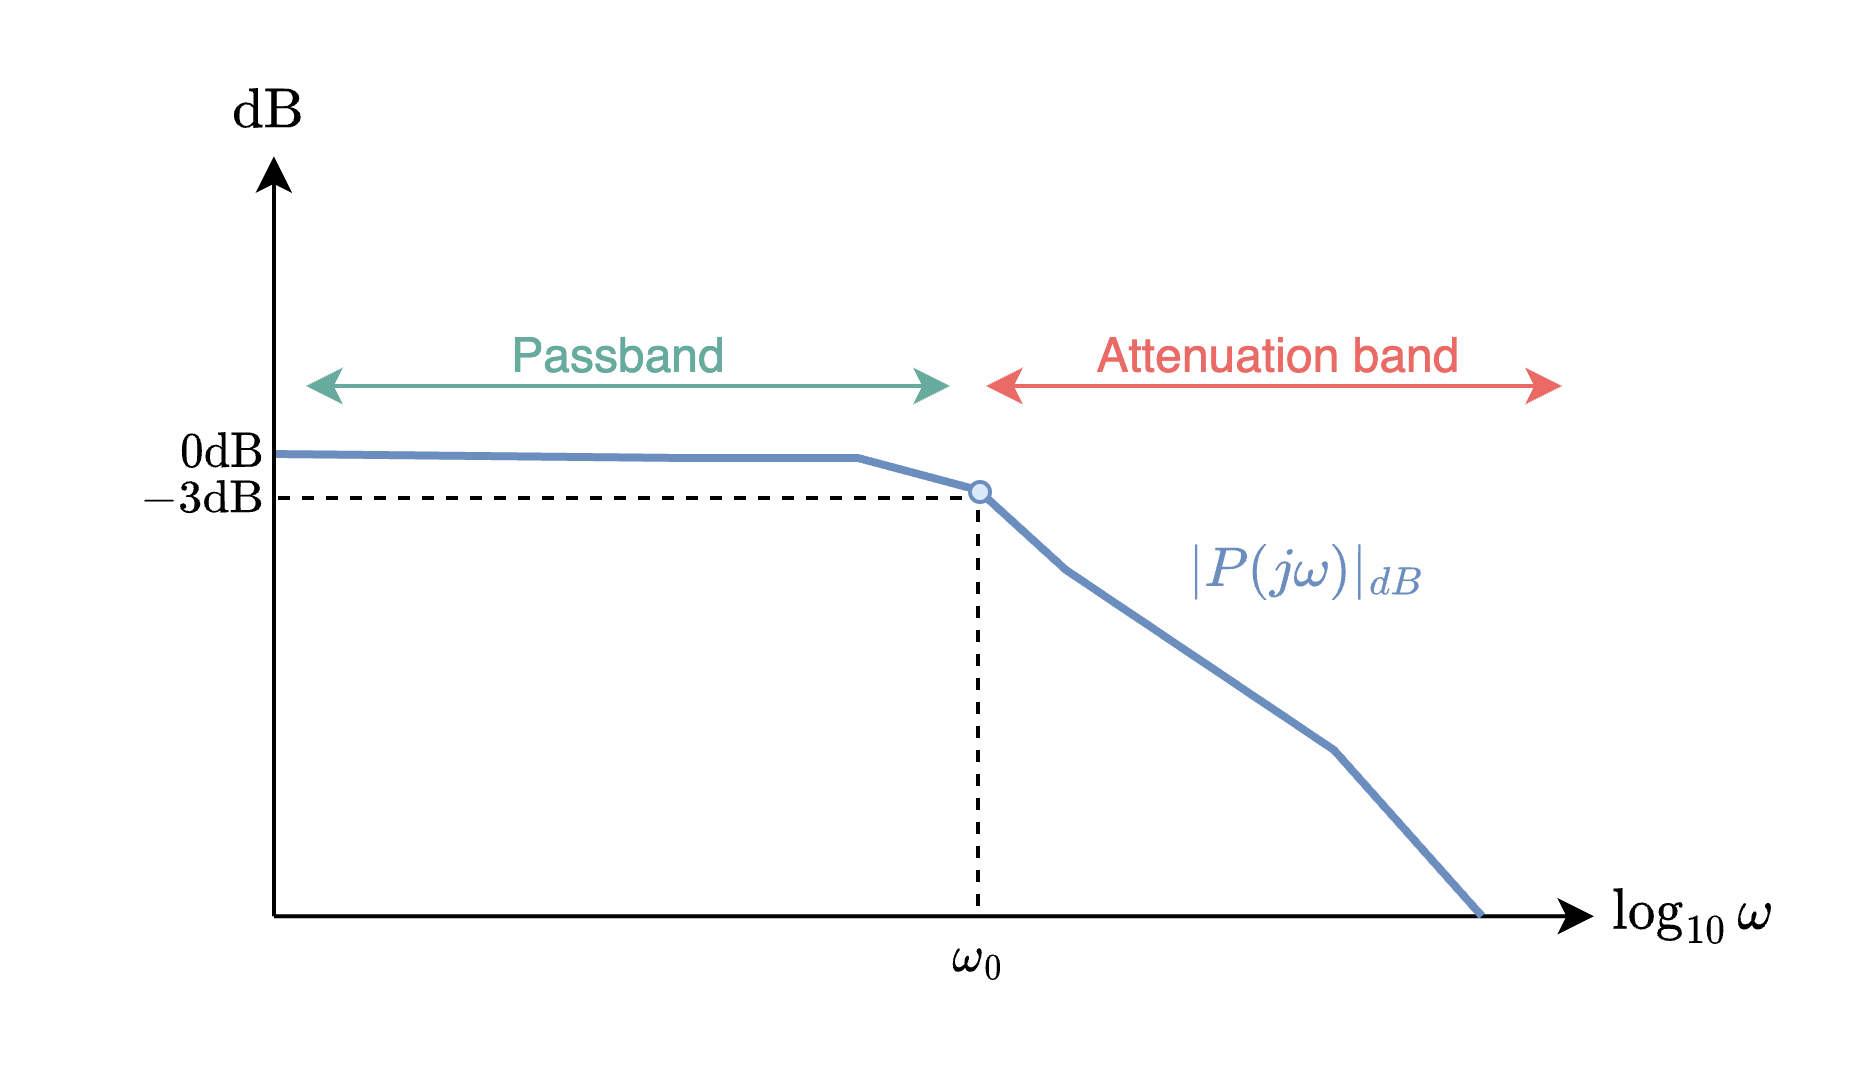

The first-order low-pass filter has the form

$P_L(s)=\frac{A_s}{s/\omega_0+1}$,

where $A_s=\lim_{s\rightarrow 0} P_L(s)$ is the DC gain of the low-pass filter, and $\omega_0$ is known as the *bandwidth* (or corner frequency) of the filter. Recall that we have already analysed this type of system in the time domain from a previous chapter, written in the form

$P_L(s)=\frac{A_s}{T_cs+1}$,

but we shall now examine its behaviour in the frequency domain. First, we should notice that the time constant is related to the bandwidth by $T_c=\frac{1}{\omega_0}$. This implies that a larger bandwidth frequency will result in a smaller time constant (and hence a shorter settling time). The frequency response of the low-pass filter is given by

$P_L(j\omega)=\lim_{s\rightarrow j
\omega} P_L(s)=\lim_{s\rightarrow j
\omega}\frac{A_s}{s/\omega_0+1}=\frac{A_s}{j\omega/\omega_0+1}$.

The (logarithmic) magnitude and phase behaviour are determined by

$|P_L(j\omega)|_{dB}=20\log_{10}\frac{A_s}{\sqrt{\frac{\omega^2}{\omega_0^2}+1}}=20\log_{10}A_s-20\log_{10}{\sqrt{\frac{\omega^2}{\omega_0^2}+1}}$,

$\angle P_L(j\omega)=\angle \{\frac{A_s}{j\omega/\omega_0+1}\}=-\frac{180}{\pi}\tan^{-1}\frac{\omega}{\omega_0}$.

Note that when $\omega=\omega_0$, the magnitude response is equal to 

$|P_L(j\omega_0)|_{dB}=20\log_{10}A_s-20\log_{10}\sqrt{2}\approx20\log_{10}A_s-3\text{dB}$.

In other words, the magnitude response at the bandwidth frequency will be $3$dB less than the DC gain of the plant. The phase response at the bandwidth frequency is determined as

$\angle P_L(j\omega_0)=-\frac{180}{\pi}\tan^{-1}(1)=-45^\circ$.

We can plot this information in a Bode diagram (for example), as shown below, along with the corresponding step response.

s = tf('s');


As = 1.4;
w0 = 5;




P = As*w0/(s+w0)
P = As/((s/w0)+1)
figure
bode(P)
figure
step(P)

For large frequencies relative to the cutoff frequency ($\omega \gg \omega_0$), the magnitude response can be approximated as

$|P_L(j\omega)|_{dB}\approx20\log_{10}A_s-20\log_{10}\omega}$.

Given that the Bode diagram plot logarithmic magnitude against logarithmic frequency ($|P_L(j\omega)|_{dB}$ vs $\log_{10}\omega$), this suggests that the magnitude response will *roll off* at a rate of $-20$dB per decade. In other words, the gradient of the slope at high frequencies will be $-20$.

We also see that for frequencies below the bandwidth frequency, $\omega<\omega_0$, the gain is approximately $0$dB, or $1$ in arithmetic units. Similarly, within the bandwidth of the filter, the phase response is close to zero. This implies that if a signal is applied to the low-pass filter with frequency content smaller than $\omega_0$ (ie within the passband), then the output of the filter will be approximately equal to input (with minor gain and phase adjustment). However, if an input signal is applied to the low-pass filter with frequency content that is much higher than the bandwidth frequency (ie in the attenuation band), then we can expect the corresponding output resposne to be reduced in magnitude, and delayed in phase. 

We can visualise this using the code below, where two input sinusoids are injected into $P_L(s)$, one with a frequency below the bandwidth frequency, and one above the bandwidth frequency.

t = linspace(0,50/w0,1e5);

u1 = sin(0.3*w0*t);
u2 = sin(5*w0*t);

figure
lsim(P,u1,t)
legend('y1(t)')
figure
lsim(P,u2,t)
legend('y2(t)')

As shown by the simulation, the response of $y_1(t)$ is approximately equal to $u_1(t)$ as the gain is approximately unitary within the passband with minimal phase lag. However, $y_2(t)$ is notably smaller and delayed, relative to $u_2(t)$, as a result of being applied within the attenuation band of the filter.

### 7.6.2 Second-order low-pass filter

A commonly encountered frequency response in control systems is the second-order low-pass filter, which has the form

$P_L(s)=\frac{k\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}=\frac{k}{s^2/\omega_n^2+(2\zeta/\omega_n) s+1}$,

where $k=\lim_{s\rightarrow 0} P_L(s)$ is the DC gain of the system, $\omega_n$ is the natural frequency, and $\zeta$ is the damping ratio. We have already analysed this type of system in the time domain from a previous chapter, but we shall now examine its behaviour in the frequency domain. The frequency response of our second-order system is

$P_L(j\omega)=\frac{k}{(j\omega)^2/\omega_n^2+(2\zeta/\omega_n)\omega j+1}=\frac{k}{1-(\omega/\omega_n)^2+j2\zeta\omega/\omega_n}$.

The magnitude response follows as

$|P_L(j\omega)|=\frac{|k|}{\sqrt{(1-(\omega/\omega_n)^2)^2+4\zeta^2\omega^2/\omega^2_n}}$,

with the logarithmic representation given by

$|P_L(j\omega)|_{dB}=20\log_{10}|k|-20\log_{10}{\sqrt{(1-(\omega/\omega_n)^2)^2+4\zeta^2\omega^2/\omega^2_n}}$.

The corresponding phase response is 


$$\begin{array}{rl}
\angle P_L(j\omega) 
&= \angle\{ \frac{k}{1-(\omega/\omega_n)^2+j2\zeta\omega/\omega_n}\},\\
&=-\angle\{ {1-(\omega/\omega_n)^2+j2\zeta\omega/\omega_n}\},\\
&=-\tan^{-1}\frac{2\zeta\omega/\omega_n}{1-\omega^2/\omega_n^2},\\
&=-\tan^{-1}\frac{2\zeta\omega\omega_n}{\omega_n^2-\omega^2}.\\
\end{array}$$


The frequency response of the second-order system can be plotted using the code below, along with the corresponding step response, where it can be shown that the peak (maximum) magnitude response occurs at

$\omega_p=\omega_n\sqrt{1-2\zeta^2}$,

and results in a peak response of

$|P_L(j\omega_p)|=M_p=\frac{k}{2\zeta\sqrt{1-\zeta^2}}$,

in arithmetic units. 

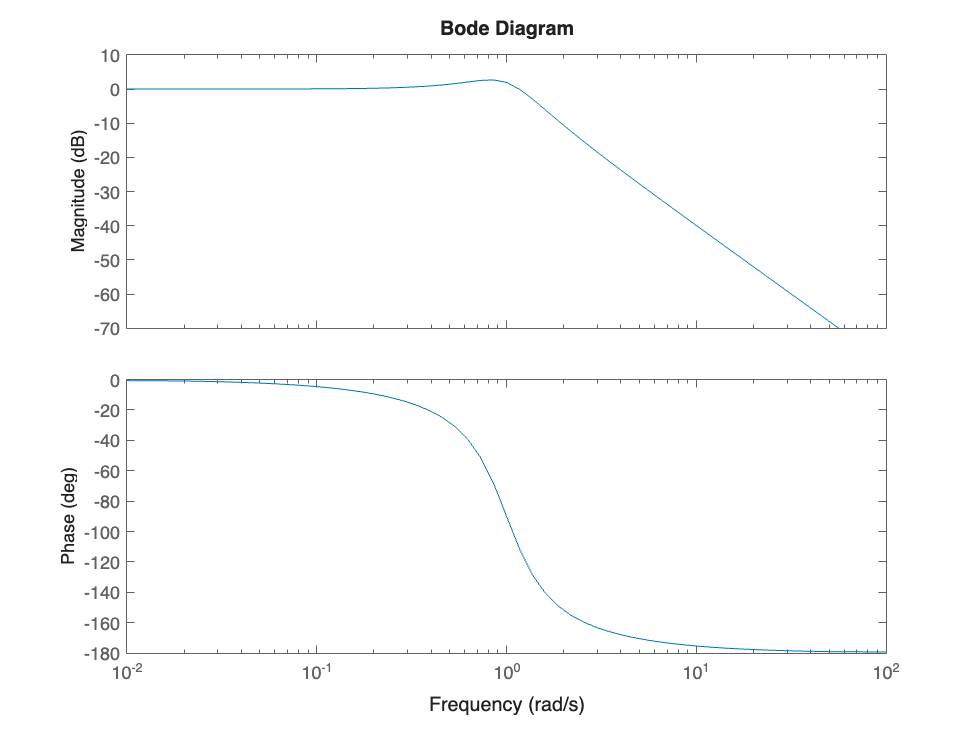

s = tf('s');


k = 1;
wn = 1;
zeta = 0.4;

P = k*wn^2/(s^2+2*zeta*wn*s+wn^2);

figure
bode(P)

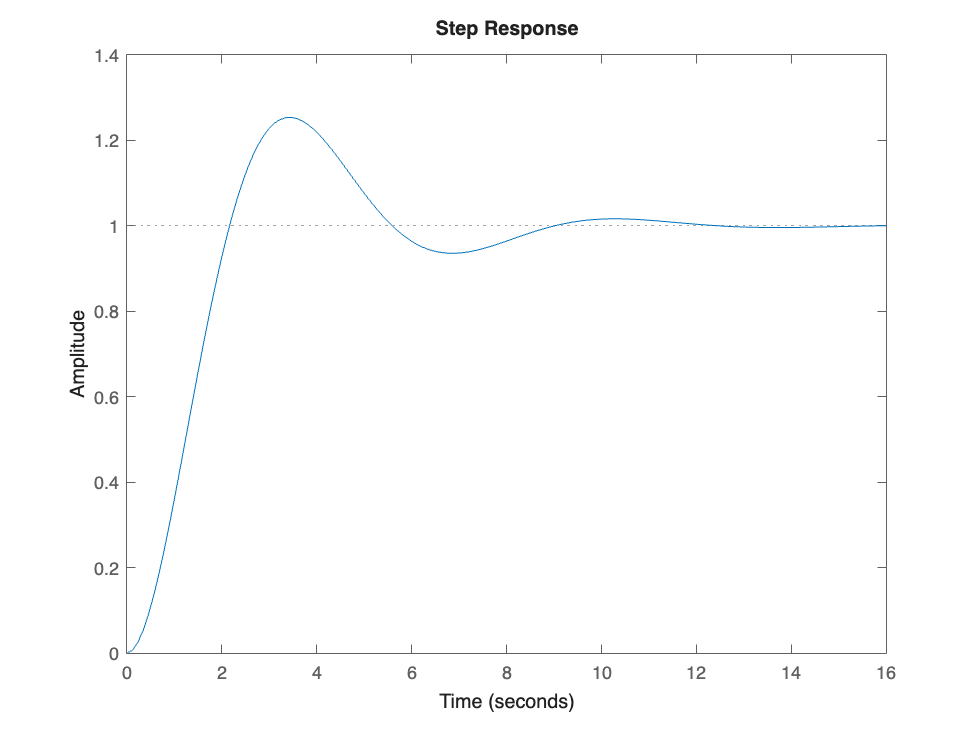

figure
step(P)

The magnitude of the peak response can be associated with the percentage overshoot of the time response, $\%OS=100e^{-\zeta\pi/\sqrt{1-\zeta^2}$, using the code below. We can therefore gauge percentage overshoot by examining the peak response.

zeta = linspace(0,1,1e2);
Mp = 1./( 2*zeta.*sqrt(1-zeta.^2) );
OS = 100*exp(-zeta*pi./sqrt(1-zeta.^2));

figure
plot(OS,Mp)
xlabel('$\%OS$',Interpreter='latex')
ylabel('$M_p$',Interpreter='latex')

As with the first-order low-pass filter, the second-order version also contains a passband and attenuation band. We use the same concept of bandwidth when determining the separation of the passband and attenuation band, where the bandwidth frequency coincides with the magnitude response $3$dB less than the DC gain, namely at $|P_L(j\omega_0)|_{dB}=20\log_{10}k-3$dB. This can be determined by equating $|P_L(j\omega_0)|=\frac{1}{\sqrt{2}}$for $k=1$, and solving for $\omega_0$, which yields

$\omega_0=\omega_n\sqrt{ (1-2\zeta^2)+\sqrt{4\zeta^4-4\zeta^2+2}}$.

Note that $20\log_{10}\frac{1}{\sqrt{2}}\approx -3$dB.

syms zeta w0 wn positive
w0 = solve( sqrt( (1-w0^2/wn^2)^2+4*zeta^2*w0^2/wn^2)==sqrt(2),w0 )

The effect of the damping ratio on the frequency response of the second-order system can be demonstrated by plotting the responses for various $\zeta$ values as a function of the normalised frequency, $\omega/\omega_n$. This is shown using the code below.

clear
s = tf('s');

k =1;
w_ = logspace(-1,1);
figure
for zeta=[0.2 0.4 0.5 0.7 0.9]
    Pw = k./(1-w_.^2+1i*2*zeta*w_);
    Pw_mag = 20*log10( abs(Pw) );
    Pw_ang = angle(Pw)*180/pi;
    
    subplot(2,1,1),hold on
    plot(w_,Pw_mag),grid on
    set(gca, 'XScale', 'log');
    
    subplot(2,1,2),hold on
    plot(w_,Pw_ang), grid on
    set(gca, 'XScale', 'log');
end
legend('$\zeta=0.2$','$\zeta=0.4$','$\zeta=0.5$','$\zeta=0.7$','$\zeta=0.9$',Interpreter='latex')

### 7.6.3 First-order high-pass filter

The high-pass filter serves to pass high-frequency signals, above the cutoff frequency, $\omega_0$, and attenuate low-frequency signals below the cutoff frequency, as shown in the image below.

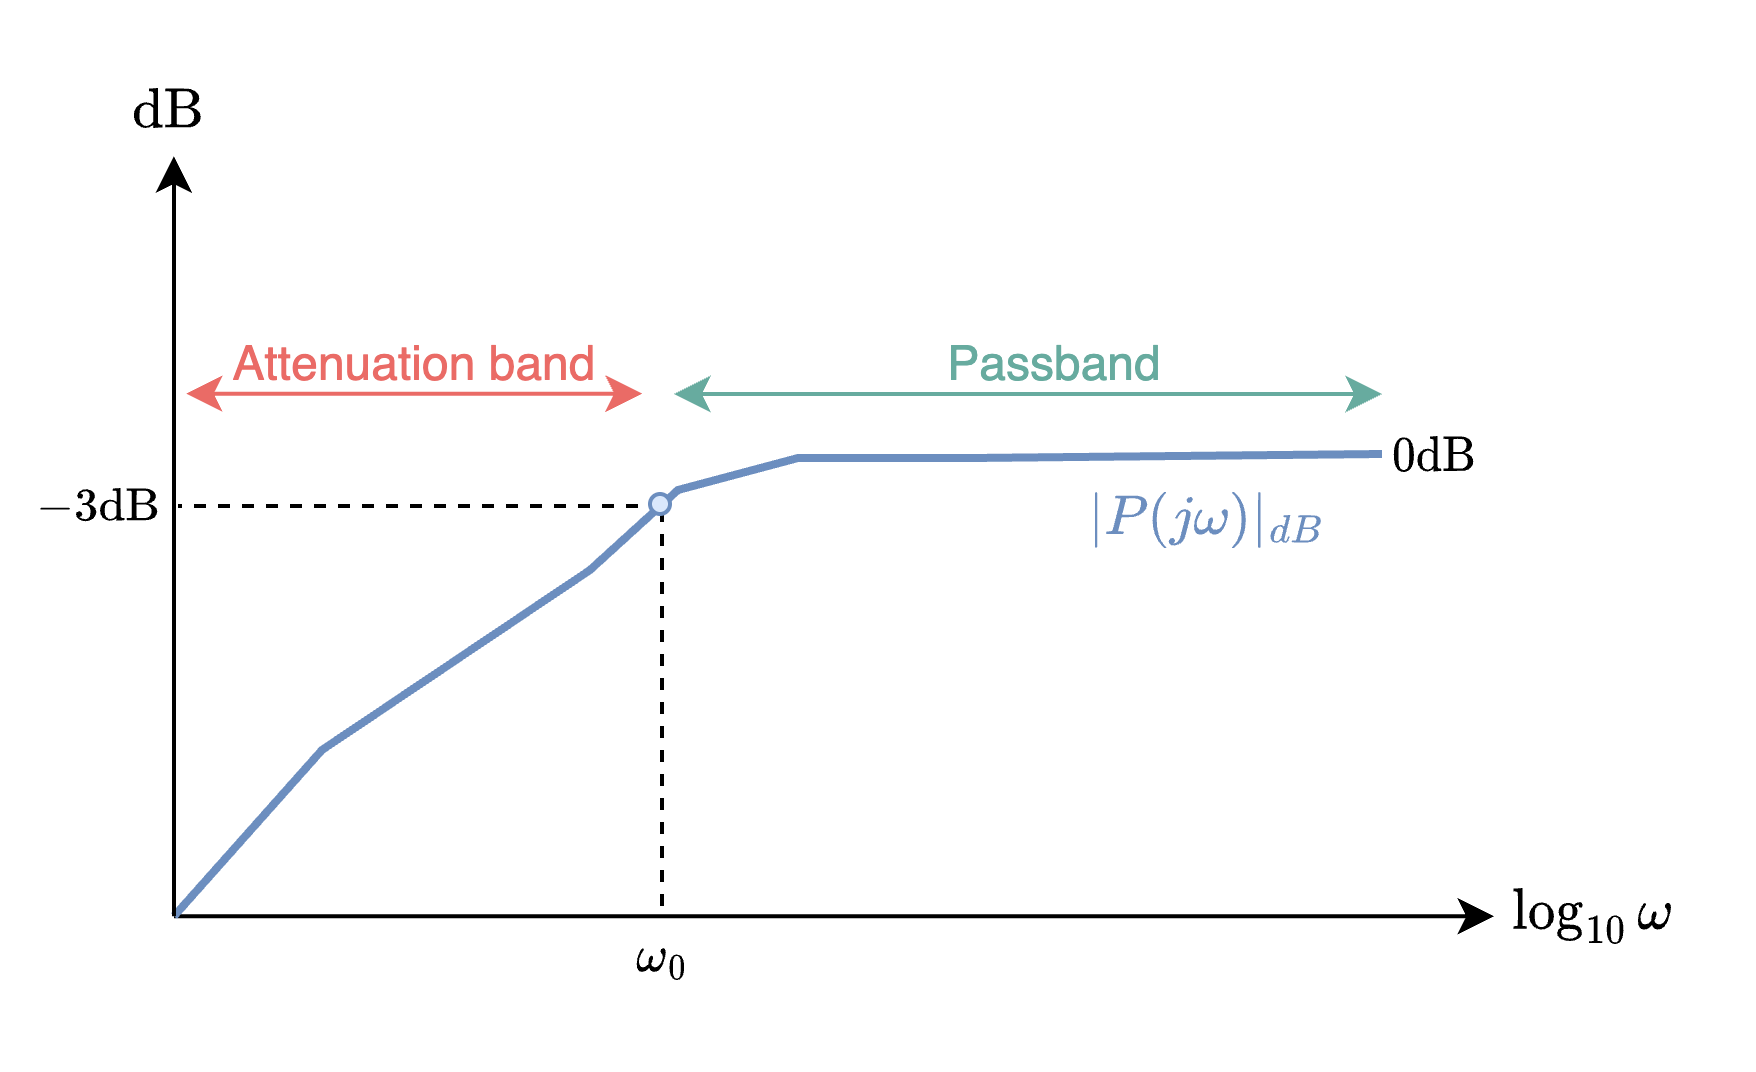

Recall that the first-order low-pass filter, with unit DC gain, has the form

$P_L(s)=\frac{1}{s/\omega_0+1}$,

where $\omega_0$ is the bandwidth of the filter. The corresponding first-order high-pass filter is known to be the complement of the low-pass filter, namely

$P_L(s)+P_H(s)=1$.

We can therefore determine the high-pass filter using


$$\begin{array}{rl}
P_H(s)
&=1-P_L(s),\\
&=1-\frac{1}{s/\omega_0+1},\\
&=\frac{s/\omega_0}{s/\omega_0+1}.
\end{array}$$


The frequency response of the high-pass filter is given by

$P_H(j\omega)=\lim_{s\rightarrow j
\omega} P_H(s)=\lim_{s\rightarrow j
\omega}\frac{s/\omega_0}{s/\omega_0+1}=\frac{j\omega/\omega_0}{j\omega/\omega_0+1}$.

The (logarithmic) magnitude and phase behaviour are determined by

$|P_H(j\omega)|_{dB}=20\log_{10}\frac{\omega/\omega_0}{\sqrt{\frac{\omega^2}{\omega_0^2}+1}}=20\log_{10}\frac{\omega}{\omega_0}-20\log_{10}{\sqrt{\frac{\omega^2}{\omega_0^2}+1}}$,

$\angle P_H(j\omega)=\angle \{\frac{j\omega/\omega_0}{j\omega/\omega_0+1}\}=90-\frac{180}{\pi}\tan^{-1}\frac{\omega}{\omega_0}$.

Note that when $\omega=\omega_0$, the magnitude response is equal to 

$|P_H(j\omega_0)|_{dB}=20\log_{10}1-20\log_{10}\sqrt{2}\approx-3\text{dB}$.

In other words, the magnitude response at the bandwidth frequency will be $3$dB less than the DC gain of the plant. The phase response at the bandwidth frequency is determined as

$\angle P_H(j\omega_0)=90-\frac{180}{\pi}\tan^{-1}(1)=45^\circ$.

The Bode diagram and corresponding step response of a first-order high-pass filter is generated using the code below.

s = tf('s');

w0 = 1;

P = s/w0/(s/w0+1)

figure
bode(P)
figure
step(P)

Signals applied well above the cutoff frequency ($\omega \gg \omega_0$) will be pass with approximately unchanged gain and phase, whereas signals with frequency well below the cutoff frequency ($\omega \ll \omega_0$) will incur gain reduction and phase lag, depending on the frequency range. We can visualise this behaviour using the code block below, where $u_1=\sin(0.3\omega_0t)$ is applied in the attenuation band, and $u_2=\sin(5\omega_0t)$ is applied within the passband.

t = linspace(0,50/w0,1e5);

u1 = sin(0.3*w0*t);
u2 = sin(5*w0*t);

figure
lsim(P,u1,t)
legend('y1(t)')
figure
lsim(P,u2,t)
legend('y2(t)')

The Bode diagrams of the first-order low- and high-pass filters are shown using the code below.

s = tf('s');

w0 = 10;

Ph = s/w0/(s/w0+1);
Pl = 1/(s/w0+1);

figure, hold on
bode(Ph)
bode(Pl)

### 7.6.4 Second-order high-pass filter

The second-order filter can be obtained in the same manner as that of the first-order equivalent, given by

$P_L(s)=\frac{k}{s^2/\omega_n^2+(2\zeta/\omega_n) s+1}$.

Exploting the complementary structure of the low- and high-pass filters, the second-order high-pass filter is obtained as


$$\begin{array}{rl}
P_H(s)
&=1-P_L(s),\\
&=1-\frac{1}{s^2/\omega_n^2+(2\zeta/\omega_n) s+1},\\
&=\frac{s^2/\omega_n^2+(2\zeta/\omega_n) s}{s^2/\omega_n^2+(2\zeta/\omega_n) s+1}.
\end{array}$$


The Bode diagram and step response of the second-order high-pass filter can be generated using the code below.

s = tf('s');

wn = 1;
zeta = 0.5;

P = (s^2/wn^2+2*zeta/wn*s)/(s^2/wn^2+2*zeta/wn*s+1);

figure
bode(P)
figure
step(P)

It may be shown that the peak response occurs at 

$\omega_p=\omega_n\sqrt{\frac{1+\sqrt{1+2\zeta^2}}{2}}$.

We can also easily prove that the magnitude response will cross the $0$dB line at

$\omega_{gc}=\frac{\omega_n}{\sqrt{2}}$.

The effect of the damping ratio on the magnitude response of the second-order system can be demonstrated by plotting the responses for various $\zeta$ values as a function of the normalised frequency, $\omega/\omega_n$. This is shown using the code below.

clear
s = tf('s');

k =1;
w_ = logspace(-1,1);

figure,hold on
for zeta=[0.2 0.4 0.5 0.7 0.9]
    Pw = (-w_.^2+1i*2*zeta.*w_)./(1-w_.^2+1i*2*zeta*w_);
    Pw_mag = 20*log10( abs(Pw) );
    
    plot(w_,Pw_mag),grid on
    set(gca, 'XScale', 'log');
end
legend('$\zeta=0.2$','$\zeta=0.4$','$\zeta=0.5$','$\zeta=0.7$','$\zeta=0.9$',Interpreter='latex',location='SouthEast')